# Machine Learning Online Class - Exercise 3 | Part 1: One-vs-all

%  Instructions
%  ------------
%  Token: aeog8YeYP0poqO7e
%  This file contains code that helps you get started on the
%  linear exercise. You will need to complete the following functions
%  in this exericse:
%
%     lrCostFunction.m (logistic regression cost function)
%     oneVsAll.m
%     predictOneVsAll.m
%     predict.m
%
%  For this exercise, you will not need to change any code in this file,
%  or any other files other than those mentioned above.
%

## Initialization

clear ; close all; clc

## Setup the parameters you will use for this part of the exercise

input_layer_size  = 400;  % 20x20 Input Images of Digits
num_labels = 10;          % 10 labels, from 1 to 10
                          % (note that we have mapped "0" to label 10)

## =========== Part 1: Loading and Visualizing Data =============

% Load Training Data
fprintf('Loading and Visualizing Data ...\n')

Loading and Visualizing Data ...


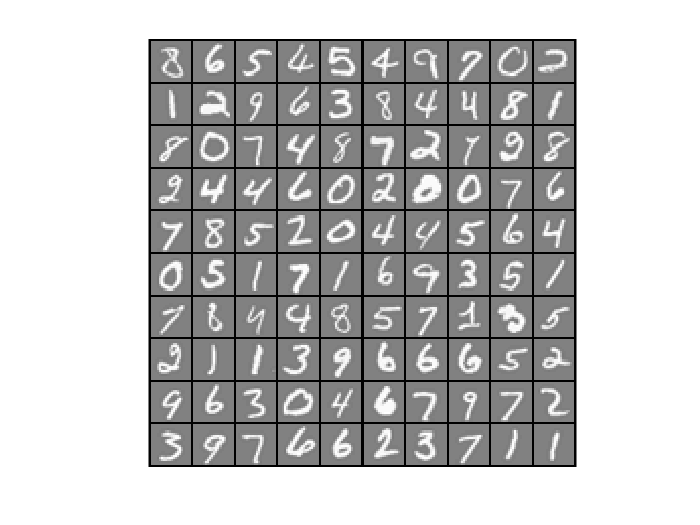


load('ex3data1.mat'); % training data stored in arrays X, y
m = size(X, 1);

% Randomly select 100 data points to display
rand_indices = randperm(m);
sel = X(rand_indices(1:100), :);

displayData(sel);


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


%pause;

## ============ Part 2a: Vectorize Logistic Regression ============

% Test case for lrCostFunction
fprintf('\nTesting lrCostFunction() with regularization');


Testing lrCostFunction() with regularization


theta_t = [-2; -1; 1; 2];
X_t = [ones(5,1) reshape(1:15,5,3)/10];
y_t = ([1;0;1;0;1] >= 0.5);
lambda_t = 3;
[J, grad] = lrCostFunction(theta_t, X_t, y_t, lambda_t);

fprintf('\nCost: %f\n', J);


Cost: 2.534819


fprintf('Expected cost: 2.534819\n');

Expected cost: 2.534819


fprintf('Gradients:\n');

Gradients:


fprintf(' %f \n', grad);

 0.146561 
 -0.548558 
 0.724722 
 1.398003 


fprintf('Expected gradients:\n');

Expected gradients:


fprintf(' 0.146561\n -0.548558\n 0.724722\n 1.398003\n');

 0.146561
 -0.548558
 0.724722
 1.398003



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


%pause;

## ============ Part 2b: One-vs-All Training ============

fprintf('\nTraining One-vs-All Logistic Regression...\n')


Training One-vs-All Logistic Regression...



lambda = 0.1;
[all_theta] = oneVsAll(X, y, num_labels, lambda);

Iteration     1 | Cost: 2.802128e-01
Iteration     2 | Cost: 9.454389e-02
Iteration     3 | Cost: 5.704641e-02
Iteration     4 | Cost: 4.688190e-02
Iteration     5 | Cost: 3.759021e-02
Iteration     6 | Cost: 3.522008e-02
Iteration     7 | Cost: 3.234531e-02
Iteration     8 | Cost: 3.145034e-02
Iteration     9 | Cost: 3.008919e-02
Iteration    10 | Cost: 2.994639e-02
Iteration    11 | Cost: 2.678528e-02
Iteration    12 | Cost: 2.660323e-02
Iteration    13 | Cost: 2.493301e-02
Iteration    14 | Cost: 2.475211e-02
Iteration    15 | Cost: 2.318421e-02
Iteration    16 | Cost: 2.287050e-02
Iteration    17 | Cost: 2.160258e-02
Iteration    18 | Cost: 2.120371e-02
Iteration    19 | Cost: 2.064125e-02
Iteration    20 | Cost: 2.055695e-02
Iteration    21 | Cost: 2.045466e-02
Iteration    22 | Cost: 2.029177e-02
Iteration    23 | Cost: 2.005296e-02
Iteration    24 | Cost: 1.995949e-02
Iteration    25 | Cost: 1.982849e-02
Iteration    26 | Cost: 1.975129e-02
Iteration    27 | Cost: 1.897815e-02
I


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


%pause;

## ================ Part 3: Predict for One-Vs-All ================

pred = predictOneVsAll(all_theta, X);

fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);